## **Lab 4 Part 1 Matlab for System Identification with Recurrent Networks**

### 1.1 Introduction 

- The objective of this task is to learn about designing and implementing recurrent network models for many-to-many type sequence problems - in this case nonlinear system identification.

- You will need the following toolboxes: 

- the Deep Learning Toolbox, 

- the System Identification Toolbox

- For related background reading to this lab, you can check the Lecture 9-10 notes/slides on Blackboard and [Chapter 10](https://www.deeplearningbook.org/contents/rnn.html) on Sequence Modelling in the book on Deep Learning (Goodfellow, Bengio and Courville, 2016).

- Work through all lab parts first, then do the quiz on Blackboard.

### 1.2 Methods

This problem is based on nonlinear black-box modeling of the dynamic behavior of a magneto-rheological (MR) fluid damper using measurements of its velocity and the damping force. 

To give some background context, MR-dampers are semi-active control devices used for reducing vibrations of various dynamic structures. MR fluids, whose viscosities depend on the input voltage/current of the device, provide controllable damping forces.

To study the behavior of such devices, an MR damper was fixed at one end to the ground and connected at the other end to a shaker table generating vibrations. The voltage of the damper was set to 1.25 v. The damping force was sampled every 0.005 s. The displacement was sampled every 0.001 s, which was then used to estimate the velocity at the sampling period of 0.005 s.The experimental setup is described in the figures below.

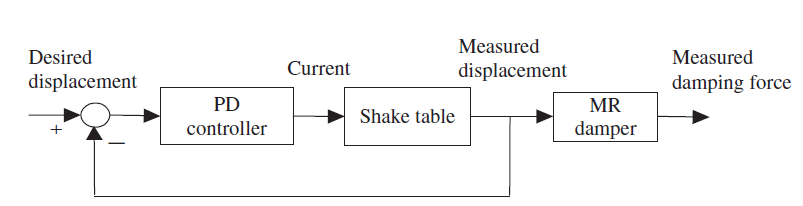

Figure 1 - Control system for the shaker table that excites the MR damper. Inputs to the MR damper are displacement of the table (converted to velocity for this modelling exercise) and output is damping force.

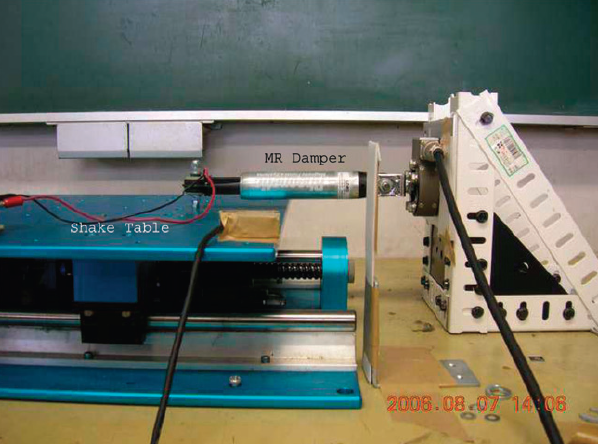

Figure 2 - Photograph of the experimental setup of the MR-damper.

This problem is based on the Matlab demo here

[https://uk.mathworks.com/help/ident/ug/nonlinear-modeling-of-a-magneto-rheological-fluid-damper.html](https://uk.mathworks.com/help/ident/ug/nonlinear-modeling-of-a-magneto-rheological-fluid-damper.html)  

and the data used in this example was provided from this paper 

J.Wang, A. Sano, T. Chen, and B. Huang. [Identification of Hammerstein systems without explicit parameterization of nonlinearity](https://www.tandfonline.com/doi/full/10.1080/00207170802382376). International Journal of Control, 2008. DOI: 10.1080/00207170802382376.

#### 1.2.1 Data

A data set containing the input and output measurements are stored in a MAT file called mrdamper.mat. The input $\mathbf{u}_t$ is the velocity [cm/s] of the damper (single-input), and the output $\mathbf{y}_t$ is the damping force [N]. The MAT file contains 3499 samples of data corresponding to a sampling rate of 0.005 s. This data will be used for all the estimation and validation tasks carried out in this example

#### 1.2.2 Model

The recurrent model we fill focus on using in this lab is the gated recurrent unit (GRU) described as


$$\mathbf{x}_{t} = \mathbf{z}_t  \odot \mathbf{x}_{t-1} + \left( 1 - \mathbf{z}_t \right)  \odot \tanh \left( \mathbf{A}_g \left( \mathbf{r}_t \odot \mathbf{x}_{t-1}  \right) + \mathbf{B}_g \mathbf{u}_{t-1} \right) \\
\hat{\mathbf{y}}_{t} = C \mathbf{x}_t$$


where the gates are


$$\mathbf{z}_t = \sigma \left( \mathbf{A}_z \mathbf{x}_{t-1} + \mathbf{B}_z \mathbf{u}_{t-1} \right) \\
\mathbf{r}_t = \sigma \left( \mathbf{A}_r \mathbf{x}_{t-1} + \mathbf{B}_r \mathbf{u}_{t-1} \right) $$


Recall that the activation function for the gates, $\sigma$, produces an output in the range 0-1. Therefore, the gates can only output in this range. 

In particular, if $\mathbf{z}_t =1$ then the state equation simplifies to 


$$\mathbf{x}_{t} = \mathbf{x}_{t-1} $$


i.e. the state is held unmodified over times-steps enabling the learning of long-term dependencies.

#### 1.2.3 Loss function

The loss function,$J\left(\theta \;\right)$, that we minimise to estimate the model parameters, $\theta$, is based on the negative log-liklihood for regression, meaning we minimise the squared error here as this is regression problem,

 
$$J\left(\theta \;\right)=\sum_{j=1}^m {\left({\hat{y\;} }_j -y_j \right)}_{\;}^{\;2} =\sum_{j=1}^m e_{j\;}^{\;2}$$


where the number of regression outputs is one because we are modelling a single-output system.

**Parameter estimation algorithm**

The parameter estimation algorithm here is based on the Adam algorithm, which combines a momemtum-like term, $v_{j}$, with an adaptive learning rate, $r_{j}$, and bias corrected versions of these terms, $\hat{v}_j$ and $\hat{r}_j$, where the j-th parameter update is


$$\theta_{j} \leftarrow \theta_{j} - \frac{\epsilon}{\sqrt{\hat{r}_{j}}} \hat{v}_{j}$$


where $\epsilon $  is a learning rate and


$$ \hat{r}_j = \frac{r_{j}}{1- \beta_1^t} \\
    \hat{v}_j = \frac{v_{j}}{1- \beta_2^t} \\
    v_{j} \leftarrow \beta_1 v_{j} + \left( 1 - \beta_1 \right)g_{j} \\
    r_{j} \leftarrow \beta_2 r_{j} + \left( 1 - \beta_2 \right)g_{j}^{2}  $$


and $g_j$ is the stochastic estimate of the loss function gradient for parameter $j$,


$$ g_{j} = \nabla_{{\theta}} \hat{J}(\theta_j)$$


and $ g_{j}$ is the estimate of the gradient of the loss function $\nabla_{{\theta}} \hat{J}({\theta})$, which is obtained from a mini-batch of data via the backpropagation through time algorithm.

#### **Model evaluation**

To evaluate the model fits, we use a normalised metric commonly used in system identification


$$F=100 \left( 1-\frac{|| y_t - \hat{y}_t ||_2}{||y_t - \bar{y}_t ||_2} \right)$$


where $F$ is model fit in percent, $\hat{y}_t$ is the model prediction, $y_t $ is a data sample and $\bar{y}_t$ is the mean of the data. For perfect fits $F=100\%$, when$F=0\%$ the prediction is equivalent to the mean of the data and the fit error is equivalent to the variance of the data (i.e. a poor fit), and the metric can become negative if the prediction error is even worse.

### 1.2 Define data

First, we load and plot the data, with input $x$ and output $y$, from the magneto-rheological damper, where the input is velocity and the output is damping force (note: usually the inputs-outputs are the other way around)

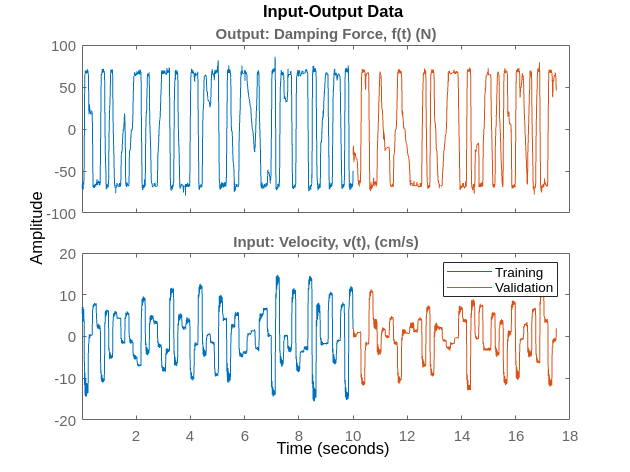

clear all
 
%% Load and prepare the training and validtion data
 
% load the data
load(fullfile(matlabroot, 'toolbox', 'ident', 'iddemos', ...
    'data', 'mrdamper.mat'));
 
% create iddata object for linear system identification 
z = iddata(F, V, Ts, 'Name', 'MR damper', ...
    'InputName', 'Input: Velocity, v(t), (cm/s)', ...
    'OutputName', 'Output: Damping Force, f(t) (N)',...
    'InputUnit', 'cm/s', 'OutputUnit', 'N');
 
% training and validation data for linear model
zt = z(1:2000);    % training data
zv = z(2001:end);  % validation data
 
% training and validation data for the recurrent network
N = length(F);        % number of data samples
utrain = V(1:2000)';  % input training data
ytrain = F(1:2000)';  % output training data
uval = V(2001:N)';    % input validation data
yval = F(2001:N)';    % output validation data
time = [0:N-1]*Ts;    % time vector
 
% Plot training and validation data
figure;
plot(zt, zv)
legend('Training','Validation')

Note: if the plot appears above that is fine, but if the plot appeaers to the right of the code and is tiny you need to change the view - click the middle, small button toward the top right of this window that says 'Output inline' when you hover the mouse over it.

### 1.3 Linear system identification benchmark using standard (non-deep learning) methods

To benchmark the deep learning recurrent model in the next section we will first identify a linear state-space model of the system dynamics (which is like a simplified form form of recurrent network model, without the nonlinear activation in the state dynamics or any gates). Then we can compare this linear model to the nonlinear deep learning to see what benefit we gain from the application of deep learning methods.

A standard linear state-space model for dynamic systems is defined in terms of a state equation and output equation, 


$$\mathbf{x}_t = A\mathbf{x}_{t-1} + B\mathbf{u}_{t-1} \\
\hat{\mathbf{y}}_{t} = C \mathbf{x}_t
$$


where $\mathbf{x}_{t} $ is the state vector, $\hat{\mathbf{y}}_{t} $ is the model output, $\mathbf{A}$ is the state transition matrix, $\mathbf{B}$ is the input matrix, and $\mathbf{C}$ is the output matrix.

The method algorithm uses the System Identification Toolbox and a method known as Subspace Identification developed in the 1990s for initial identification of the model, followed by gradient-based parameter optimisation. So the main differences 

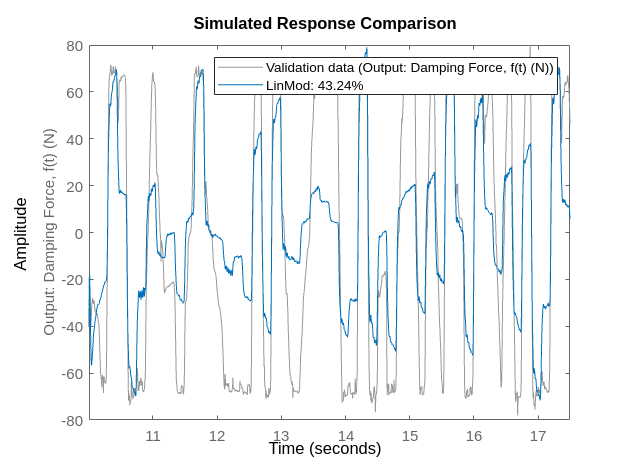

%% identify linear state-space model for benchmarking
LinMod = ssest(zt); % identify a linear state-space model of order 3
 
% Plot results
figure;
compare(zv, LinMod) % compare model to validation data

### 1.4 Recurrent network modelling

Now we setup a GRU recurrent network.

The recurrent network has a sequenceInputLayer, because we are dealing with an input sequence, which is the damper velocity over time-steps. There is only a single input (velocity) at each sample time. (A recurrent network can easily handle multiple inputs, but that is not necessary here)

The recurrent network has a single GRU cell in the hidden layer, which is all that is really needed here. Multiple GRU cells can be stacked to create a deep recurrent network if needed – the number of layers is a hyperparameter for tuning, just like in convolutional networks. Note that the number of units in the hidden layer here is set to 10, which is another hyperparameter.  This hyperparameter was tuned through a few initial experiments.

The network output is a fullyConnectedLayer  and there is a regressionLayer at the output to define this network as a regression-type (note that the output being modelled is continuous values of damper force, so this is a regression-type of problem). 

The training options for the optimization of network parameters are very similar to those used in any deep learning problem where gradient descent methods are used to estimate the parameters. Note in this case we specify the use of the Adam algorithm, and also that the learning rate is set relatively high to 0.2 – this was tuned through a few initial experiments.

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        57.97 |        53.66 |    1680.0220 |    1439.8269 |          0.2000 |
|      50 |          50 |       00:00:02 |         6.61 |         9.59 |      21.8316 |      45.9862 |          0.2000 |
|     100 |         100 |       00:00:04 |         4.98 |        11.54 |      12.4155 |      66.6019 |          0.2000 |
|     150 |         150 |       00:00:06 |         4.84 |        10.45 |      11.7175 |      54.5531 |          0.2000 |
|     200 |         200 |       

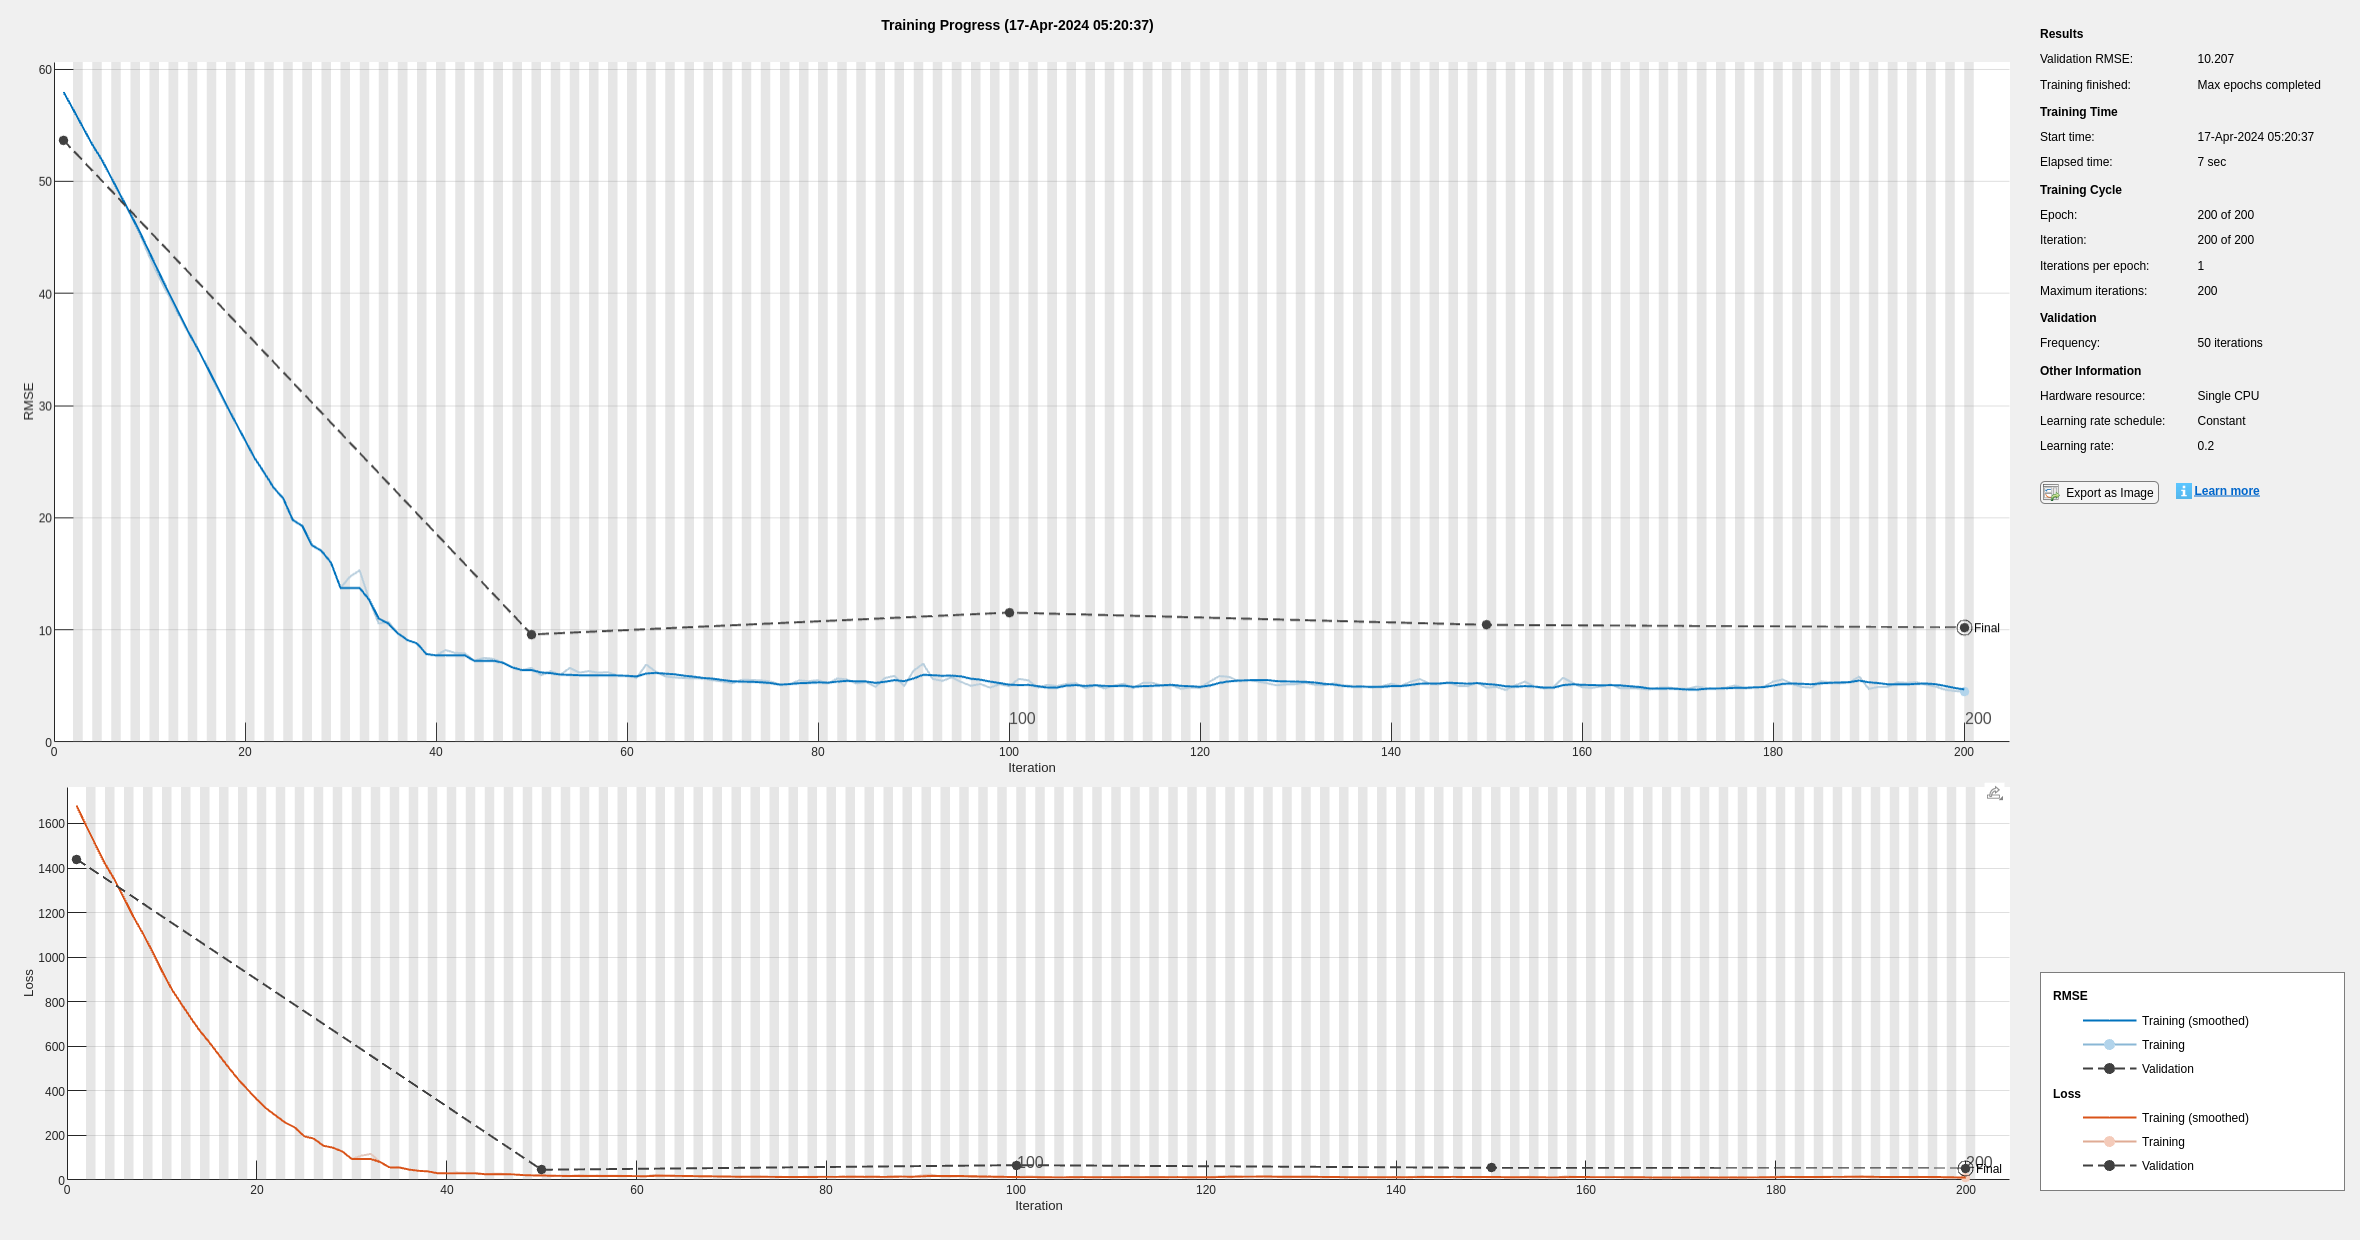

%% define and train recurrent recurrent network
 
% define network architecture 
nu = 1;  % number of inputs 
ny = 1;  % number of outputs 
nx = 10;  % number of hidden units (state dimension)
 
% define recurrent network layers
Networklayers = [...
    sequenceInputLayer(nu) ...
    lstmLayer(nx) ...
    fullyConnectedLayer(ny) ...
    regressionLayer];
 
% define training options
options = trainingOptions('adam', ...
    'MaxEpochs',200, ...
    'MiniBatchSize',200, ...
    'GradientThreshold',10, ...
    'Shuffle','once', ...
    'Plots','training-progress',...
    'ExecutionEnvironment','cpu',...
    'InitialLearnRate', 0.2,...
    'Verbose',1,...
    'ValidationData',[{uval} {yval}]);
 
% train network
net = trainNetwork(utrain,ytrain,Networklayers,options);

### 1.5 Plot the output and evaluate results

We can now examine the model predictions from the linear state-space model and the GRU model.

%% evaluate model
 
% Simulate recurrent model using validation data 
yvalnet = predict(net,uval);

% Simulate linear model using validation data
yval_full_sim = sim(LinMod,iddata([],uval',Ts));
yvallin = yval_full_sim.OutputData;

% Calculate the prediction accuracy using a fit metric
F_GRU = 100*(1 - (sqrt(sum( (abs(yval - yvalnet)).^2)) / sqrt(sum((abs(yval - mean(yval))).^2))));
F_Lin = 100*(1 - (sqrt(sum( (abs(yval - yvallin')).^2)) / sqrt(sum((abs(yval - mean(yval))).^2))));
disp(['Fit GRU: ' num2str(F_GRU) '%'])

Fit GRU: 66.039%


disp(['Fit Linear: ' num2str(F_Lin) '%'])

Fit Linear: 42.1891%


Plot outputs

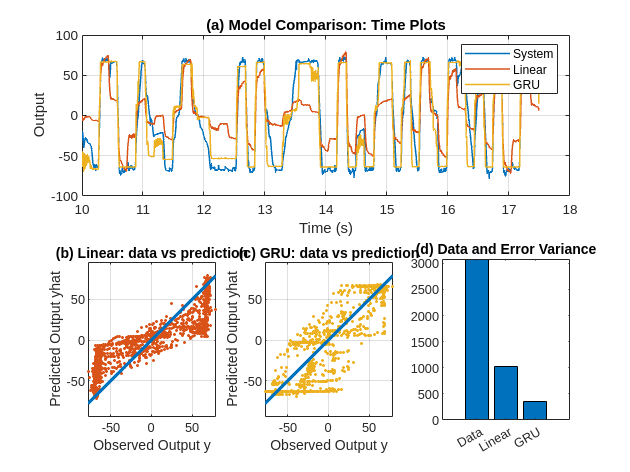

% setup new figure for plotting results
figure
cols = get(gca,'DefaultAxesColorOrder');
 
% model predictions over time
subplot(2,3,[1 2 3])
title('Time-domain response')
plot(time(2001:end),yval,...
    time(2001:end),yvallin, ...
    time(2001:end), yvalnet,'linewidth',1)
grid on
legend('System','Linear','GRU')
title('(a) Model Comparison: Time Plots')
xlabel('Time (s)');
ylabel('Output')
 
% linear model: data vs predictions
subplot(2,3,4)
plot(yval,yvallin,'.','color',cols(2,:)); hold on
plot([min(yval) max(yval)],[min(yval) max(yval)],'color',cols(1,:),'linewidth',2); 
title('(b) Linear: data vs prediction')
xlabel('Observed Output y');
ylabel('Predicted Output yhat')
grid on
axis equal
 
% recurrent model: data vs predictions
subplot(2,3,5)
plot(yval,yvalnet,'.','color',cols(3,:)); hold on
plot([min(yval) max(yval)],[min(yval) max(yval)],'color',cols(1,:),'linewidth',2); 
title('(c) GRU: data vs prediction')
xlabel('Observed Output y');
ylabel('Predicted Output yhat')
grid on
axis equal
 
% plot of data and error variance for both models
subplot(2,3,6)
bar([1 2 3],[var(yval) var(yval-yvallin') var(yval-yvalnet)])
title('(d) Data and Error Variance');
set(gca,'xticklabel',{'Data','Linear','GRU'})

The plot above shows the output from the GRU recurrent network compared to the linear state-space model. Notice in panel (a) how the GRU network captures the full amplitude of the system response in a way that the linear state-space model does not. This demonstrates that the GRU network is capturing nonlinear dynamics in the response that a linear model cannot represent. 

In panels (b) and (c) the model predictions are plotted against the data – ideally the data in such a plot should lie on a straight line through the origin, of slope equal to one – this would indicate that data=model predictions, i.e. a perfect model. That is never possible, but this type of plot does show up features such as un-captured nonlinearities, as in panel (b) for the linear model, whereas in panel (c) for the recurrent network, the data points are more randomly distributed about the line through the origin.  Finally, panel (d) shows the error variance for both models, compared to the data variance – clearly, the GRU model has significantly improved on the accuracy of the linear model.

% End of Lab Part 1 - move onto next part